# Event distance analysis (arena anti-events)

### 1 Simplify events by removing M duplicates and selecting specified K 

If multiple events are significant starting at the same time for the same length, only keep the one with highest number of neurons 

% get simplified events and antievents
load('em_arena_antievent_0.05.mat')
anti=rem_dup_em(anti,'nround',1);
[N,nm]=size(anti{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
% antievents
allt=cell(N,nm);allm=cell(N,nm);allk=cell(N,nm);
for p=1:N
    for m=1:nm
        [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,anti{1,1}.K{p,m},anti{1,1}.M{p,m},anti{1,1}.time{p,m});
    end
end
anti{1,1}.allt=allt;anti{1,1}.allm=allm;anti{1,1}.klist=klist;anti{1,1}.allk=allk;

### Calculate distance between events for each k 

For each event in one animal, calculate the distance between the center of this event and the nearest event in the other animal. 

Get within pair distance for each event and between pair distance for each event 

% merge events from the two rounds of detection 
ev_merge=cell(N,nm); % center of all events 
for p=1:N
    for m=1:nm
        ev_merge{p,m}=cell(1,4);
        for k=1:4
            % merge events from the two rounds of detection 
            ev_merge{p,m}{k}=anti{1,1}.allt{p,m}{k}+klist{k}/2;
        end
    end
end
% within-pair distance
distwithin=cell(N,nm);distbetween=cell(N,nm);
for p=1:N
    for m=1:2
        distwithin{p,m}=cell(1,4);distbetween{p,m}=cell(1,4);
        for k=1:4
            if isempty(ev_merge{p,m}{k})
               continue 
            end
            % within pair
            distwithin{p,m}{k}=eventdist(ev_merge{p,m}{k},ev_merge{p,setdiff([1 2],m)}{k}); 
            distbetween{p,m}{k}=[];
            for p1=setdiff(1:N,p) % exclude the same pair index
                for m1=1:2
                    if isempty(ev_merge{p1,m1}{k})
                        continue 
                    end
                    distbetween{p,m}{k}(end+1,:)=eventdist(ev_merge{p,m}{k},ev_merge{p1,m1}{k}); 
                end
            end
        end
    end 
end

### Plot distribution of event distance 

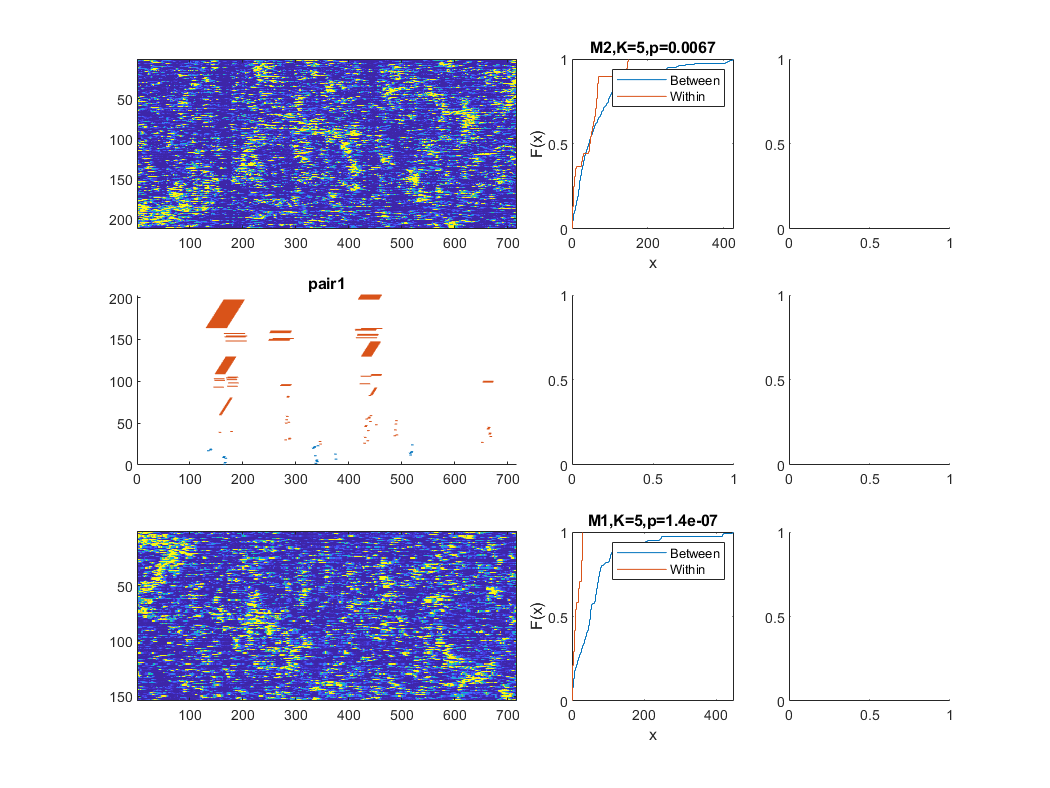

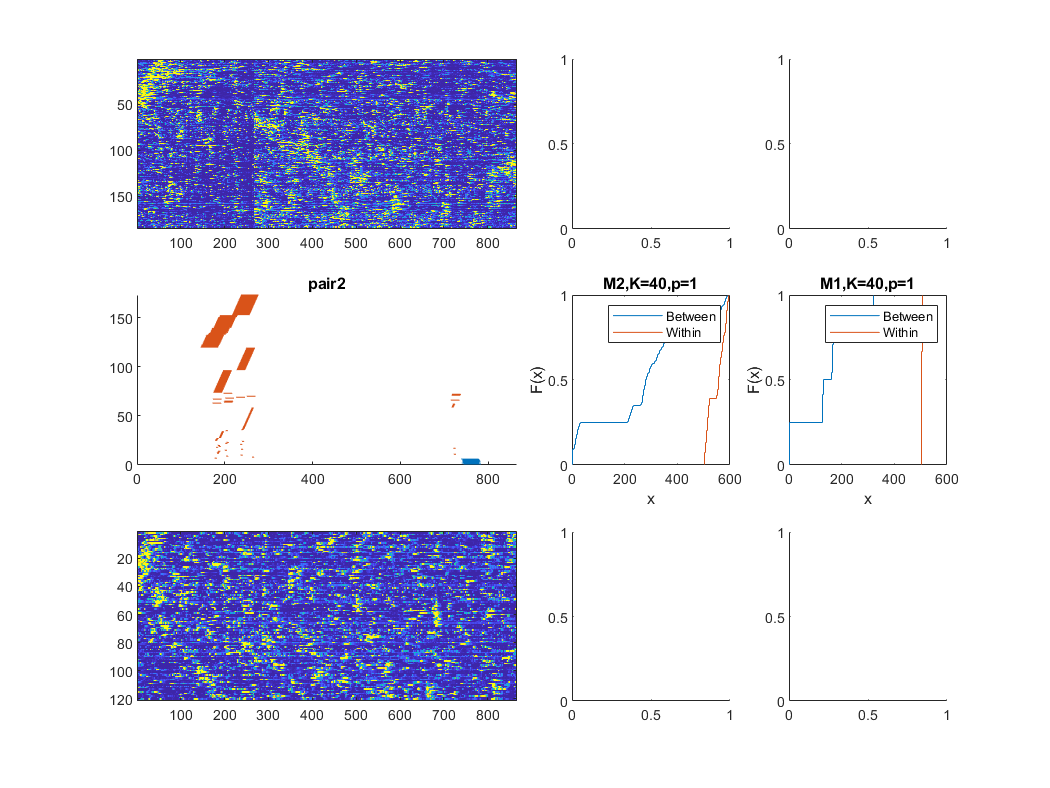

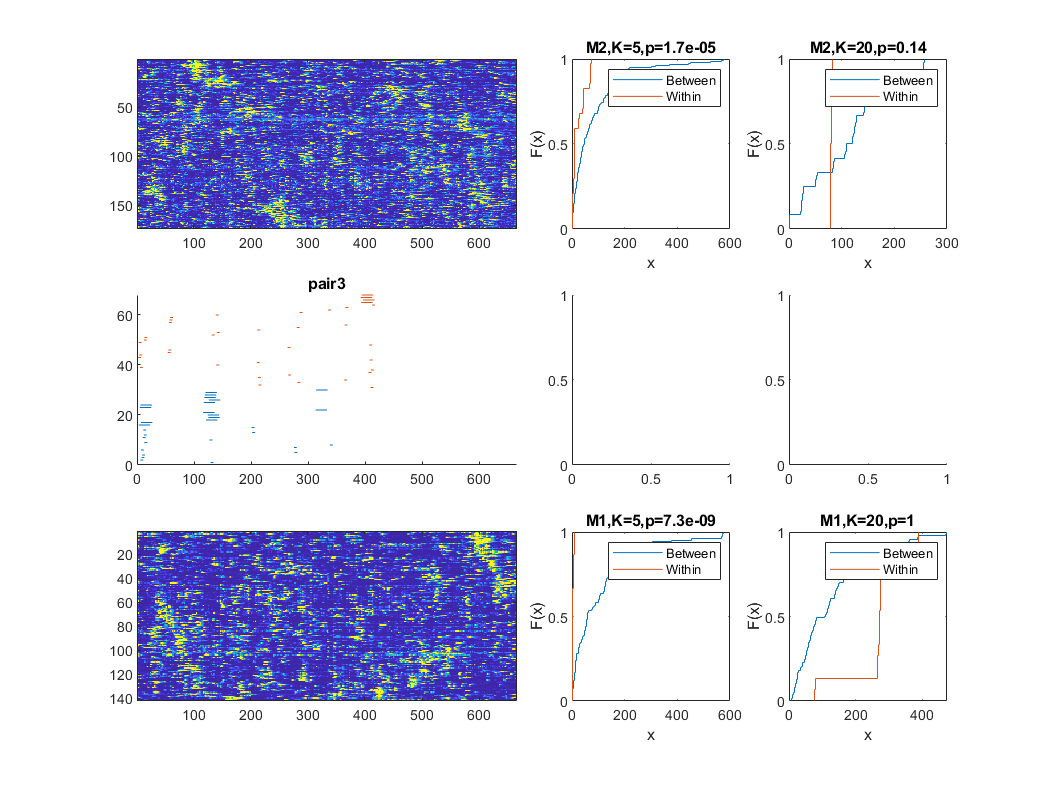

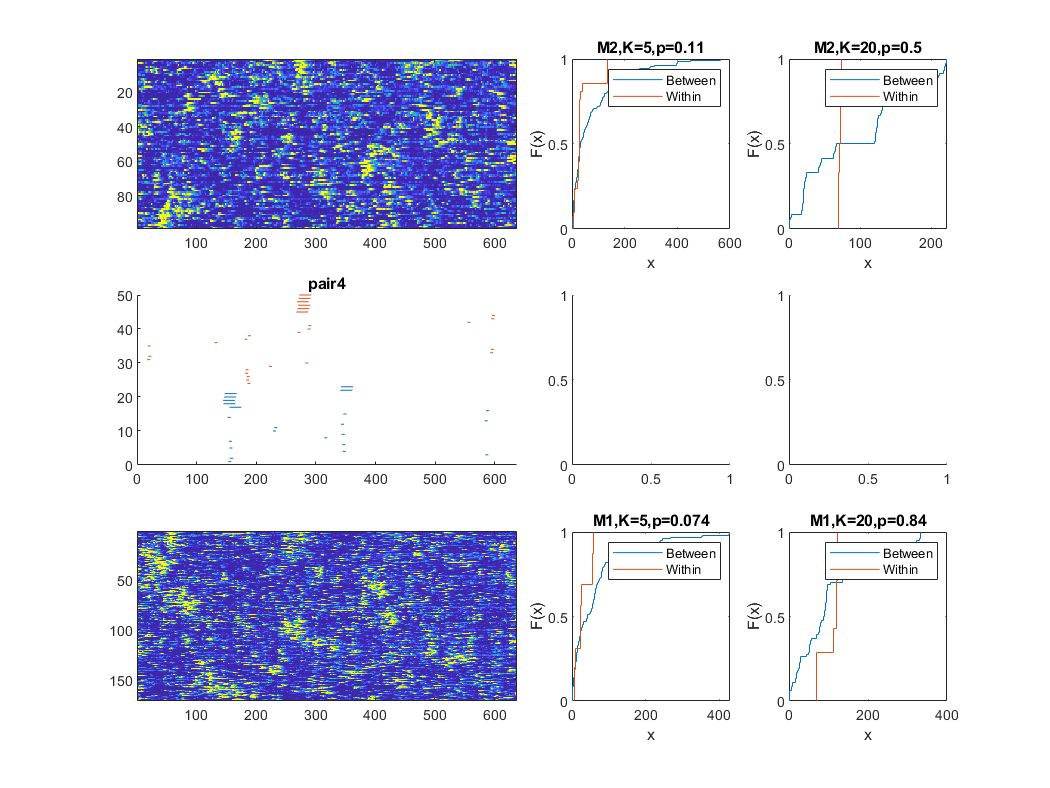

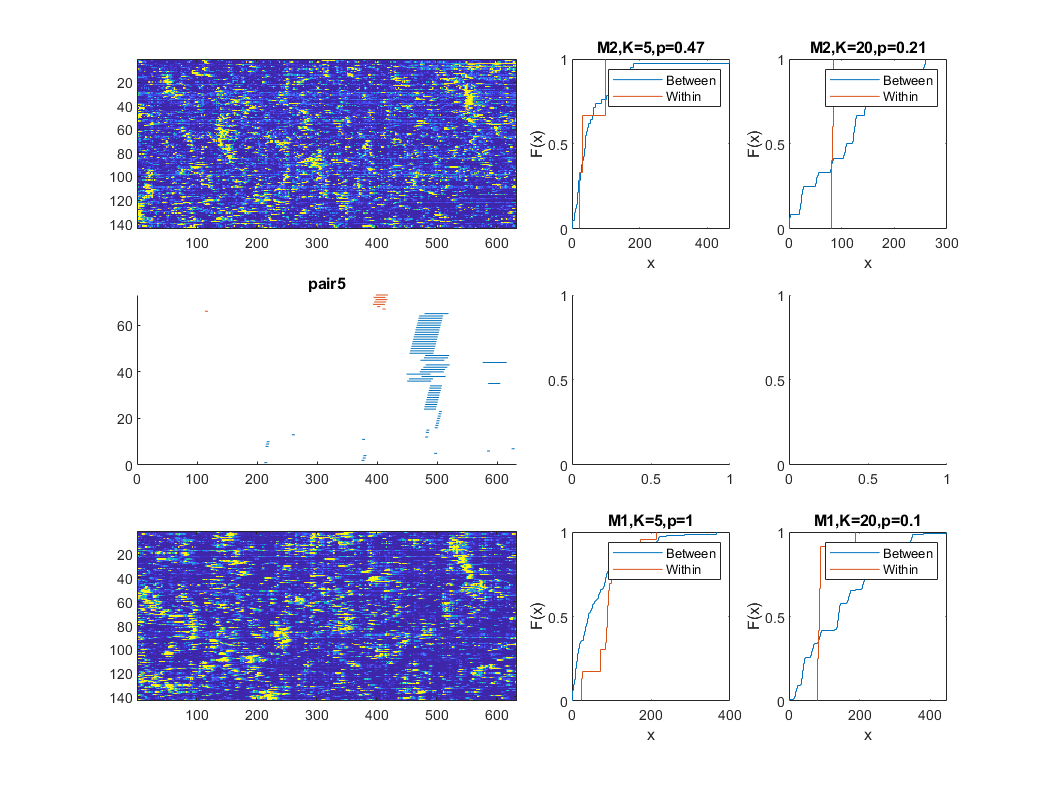

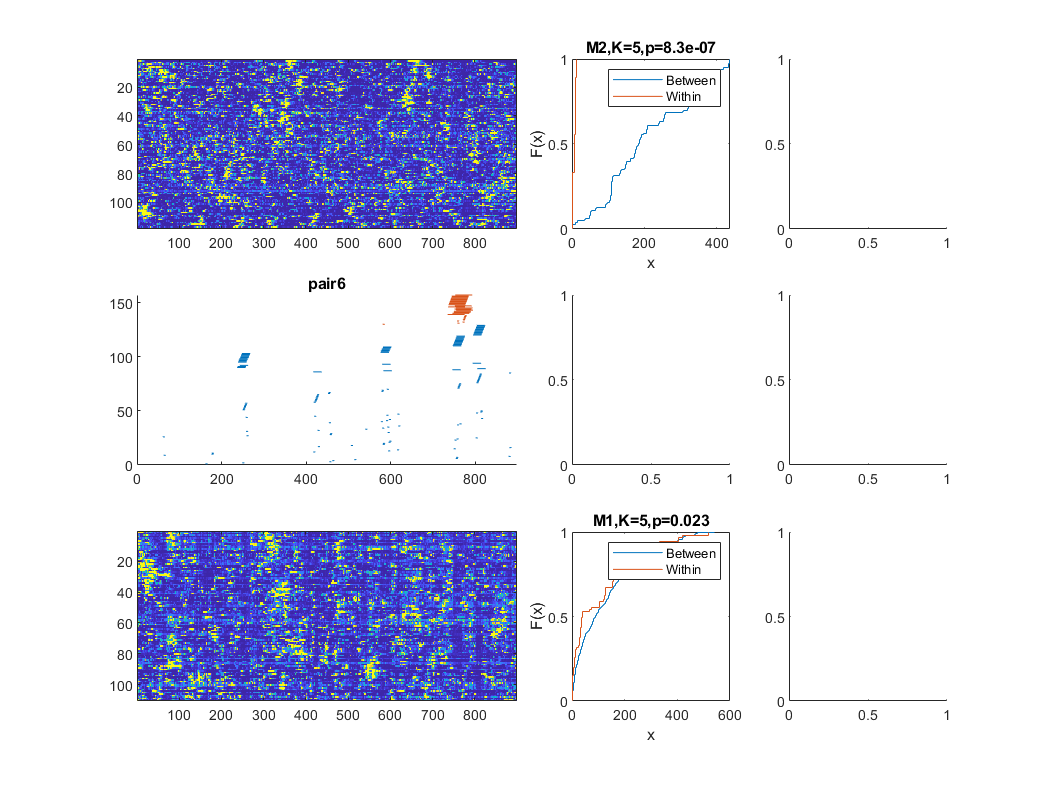

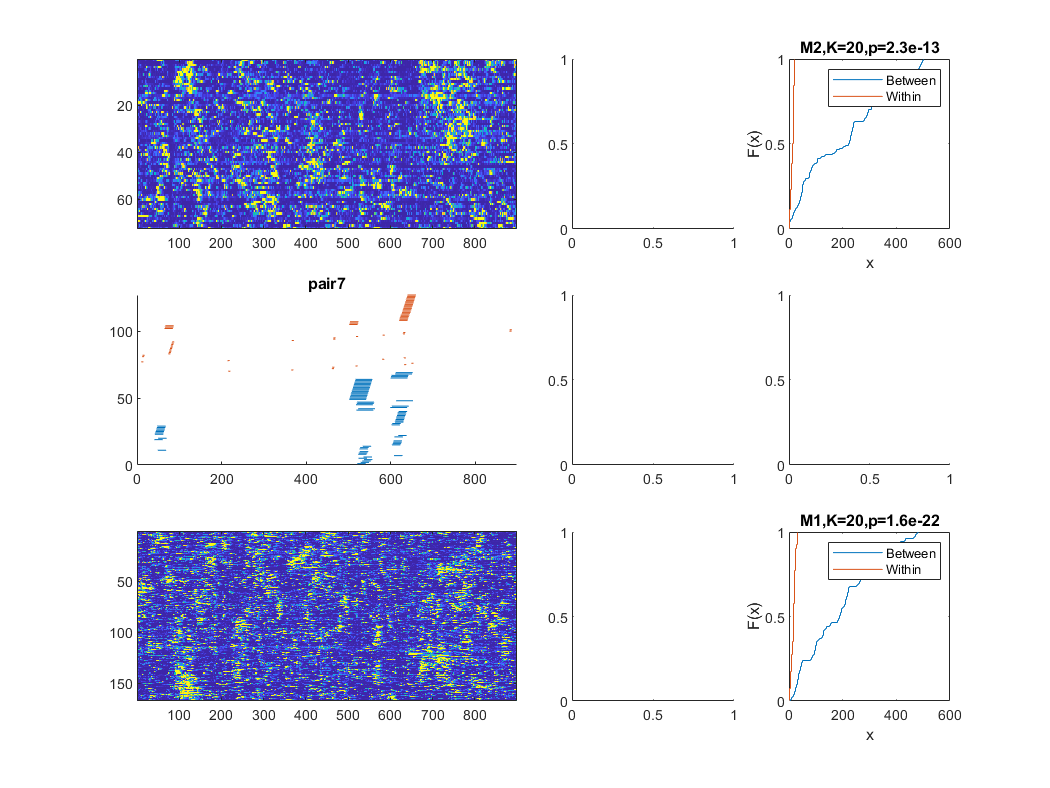

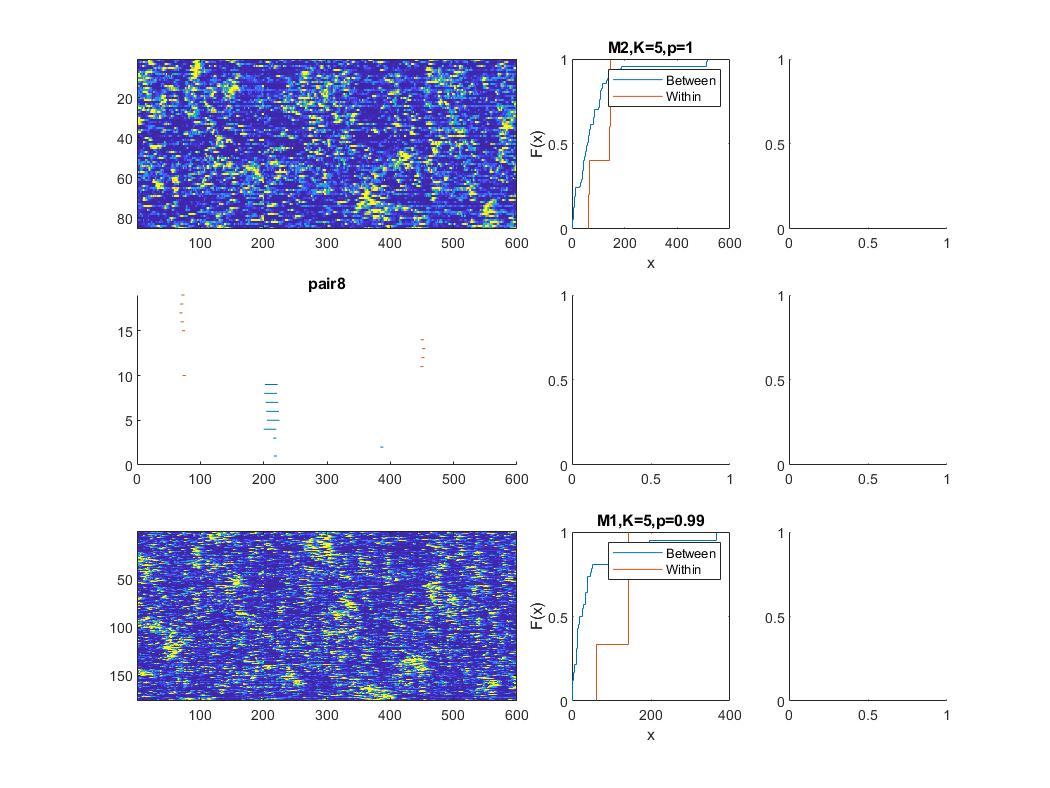

close all 
rs=NaN(3,N,nm);
for n=1:N
    p=n;
    f=figure;f.Position(3)=2*f.Position(4);f.Position(4)=1.5*f.Position(4);
    subplot(3,4,[1 2])
    S0=anti{1,1}.ca_cl{p,2};
    ops.iPC=1:35;
    [isort1, ~, ~] = mapTmap(S0, ops);
    imagesc(S0(isort1,:))
    subplot(3,4,[5 6])
    totalt=size(anti{1,1}.ca_cl{p,1},2);
    et11=anti{1,1}.allt{p,1};
    et21=anti{1,1}.allt{p,2};
    maxy=eventplot_lines(et11,anti{1,1}.allk{p,1},1:totalt);
    hold on
    maxy=eventplot_lines(et21,anti{1,1}.allk{p,2},1:totalt,'y0',maxy,"col",[0.8500 0.3250 0.0980]);
    hold off
    xlim([0 totalt]);ylim([0 maxy])
    title(sprintf('pair%d',p))
    subplot(3,4,[9 10])
    S0=anti{1,1}.ca_cl{p,1};
    [isort1, ~, ~] = mapTmap(S0, ops);
    imagesc(S0(isort1,:))
    pind{1}=[11,12,8];pind{2}=[3,4,7]; % subplot index for hist
    for k=1:3
        for m=1:2
    subplot(3,4,pind{m}(k))
    if isempty(distwithin{n,m}{k}(:))
        continue
    end
    ecdf(distbetween{n,m}{k}(:));
    hold on
    ecdf(distwithin{n,m}{k}(:));
    legend({'Between','Within'})
    rs(k,p,m)=ranksum(distbetween{n,m}{k}(:),distwithin{n,m}{k}(:),'tail',"right");
    title(sprintf('M%d,K=%d,p=%.2g',m,klist{k},rs(k,p,m)))
        end 
    end
end

### Summary of All Mice 

rs=reshape(rs,3,[]);
smy=[sum(rs'<=0.05);sum(~isnan(rs'))];
array2table(smy,"RowNames",{'nSignificant','nData'},'VariableNames',{'K=5','K=20','K=40'})

ans = 2×3 table
                    K=5    K=20    K=40
                    ___    ____    ____

    nSignificant     6       2      0  
    nData           14      10      2  
